# Transmit OFDM Samples with ADALM-PLUTO

This script opens a file containing IQ samples "OFDM_IQ_samples_simulation.mat" and transmit them as a waveform with ADALM-PLUTO SDR.

#### PLUTO-SDR Settings

As for the BPSK signal, first, we need to establish the configuration parameters for the pluto. 

Like in the previous examples, the carrier frequency (***fc***) is set to **868 MHz**, which is often used for ISM band applications like IoT devices. And, the transmission gain (***txGain***) is set to **-20 dB**, controlling the output power of the transmitted signal.

fc     = 868e6; % Carrier frequency
txGain = -20;   % Transmit gain (dB)

#### Get IQ samples and data from file

Now, the IQ samples are loaded from the file "***OFDM_IQ_samples_simulation.mat***`"`. The **sampling frequency (*****fs*****)** is retrieved from the file's metadata. A **time vector (*****t*****)** is recreated from the sample indices to visualize the signal over time, and the **IQ data (*****txSamples*****)** contains the actual OFDM-modulated samples that will be transmitted. 

These steps are exactly the same we did for the BPSK case. 

% Get IQ samples and data from file
load OFDM_IQ_samples_simulation_less2.mat % Load file containing IQ samples
fs = IQSamples.DataInfo.UserData.fs; % Extract sampling frequency
t = (IQSamples.Time).*(1/fs);        % Recreate time vector if needed
txSamples = IQSamples.Data;          % Extract IQ samples


Now, it's important to ensure that the samples we are going to transmit, retrieved from the file "*OFDM_IQ_samples_simulation.mat*", continue being what we are expecting. 

Represeting the graph, we can see how the signal was previously stored correctly, since the OFDM signal is exactly the burst signal we generated before.

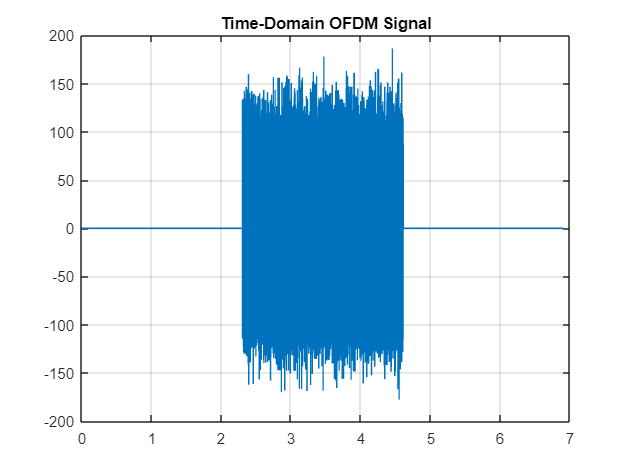

% Plot figure to verify it is as expected
figure
plot(t, real(txSamples))
grid on
title("Time-Domain OFDM Signal")

#### Open a session on PLUTO-SDR

The following step is to configure and create the transmitter object for the Pluto, which again uses exactly the same code as for the BPSK signal. 

Firstly, we use a **sdrtx Object **to create a transmitter object (*tx*) to interface with the ADALM-PLUTO SDR. Then as parameters we specify:

- `"`**Pluto**`"`: Specifies the device as a PLUTO SDR.

- `"`**RadioID**`", "`**usb:0**`"`: Specifies the ID of the connected device (e.g., USB port).

- **" BasebandSampleRate "**: Matches the IQ sample rate (***fs***) to ensure proper playback.

- **" CenterFrequency "**: Sets the carrier frequency to ***fc***.

- **" Gain "**: Sets the transmission gain (***txGain***).

tx = sdrtx(...
    "Pluto",...
     "RadioID", "usb:0", ...
    "BasebandSampleRate",fs,...
    "CenterFrequency",fc, ...
    "Gain", txGain);

Let's verify before doing the transmission that both Plutos (for transmission and reception) are properly connected to the computer. 

findPlutoRadio

ans = struct with fields:
      RadioID: 'usb:0'
    SerialNum: '104473e6a60f0001f4ff3200252c17de80'


#### Use Transmit Repeat function to generate signal continuously

We already have everything prepared, so we can start the transmission. We use the ***transmitRepeat()*** function that sends the IQ samples continuously. As for the BPSK case, this allows the ADALM-PLUTO SDR to loop the provided signal indefinitely without additional input from MATLAB. Therefore, in our application, we are going to do a constant transmission.

transmitRepeat(tx,txSamples)

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


Once the previous command is running, we are using the first Pluto for transmission. The next step would be to start receiving with the second Pluto. For doing this, we open a new MATLAB instance, and we run there the file ***"OFDM_Receiver.mlx***", that is the third and last step of this process.

#### Stop transmission

In order to free the PLUTO SDR resources, once we hace received with the second one everything we needed, we can use the *release* command. This will stop the transmission and disconnect the MATLAB session from the SDR. In this notebook, this line of code is commented again, so the transmission continues. You can uncomment it when you need to stop the transmitter.

%release(tx)